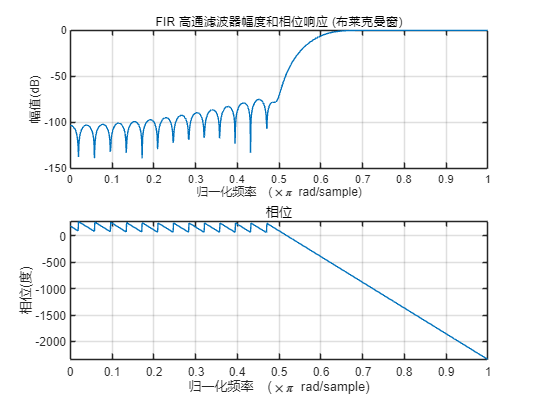

% 设计参数
wp = 0.7 * pi;       % 通带截止频率 (绿色注释：高通滤波器的通带 > 阻带)
ws = 0.5 * pi;       % 阻带截止频率 (绿色注释：归一化频率)
As = 55;             % 阻带衰减 (dB) (绿色注释：布莱克曼窗满足此要求)

% 选择布莱克曼窗 (Blackman) (绿色注释：窗函数选择基于阻带衰减)
wc = (wp + ws) / 2;  % 截止频率 (绿色注释：中间频率)
delta_w = wp - ws;   % 过渡带宽 (绿色注释：注意高通是 wp - ws)

% 计算滤波器长度 N (绿色注释：布莱克曼窗过渡带公式 N ≈ 11π/Δω)
N = ceil(11 * pi / delta_w);  
if mod(N, 2) == 0
    N = N + 1;       % 确保 N 是奇数 (绿色注释：线性相位要求)
end

% 设计 FIR 滤波器 (绿色注释：'high' 表示高通)
h = fir1(N-1, wc/pi, 'high', blackman(N));

% 绘制频率响应 (绿色注释：默认幅度和相位曲线)
freqz(h, 1, 1024);
title('FIR 高通滤波器幅度和相位响应 (布莱克曼窗)');

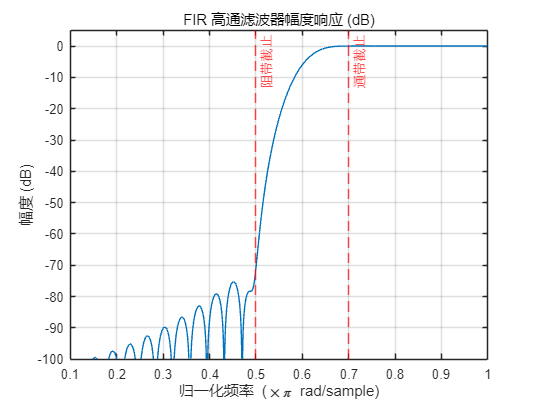


% 绘制幅度响应 (dB) (绿色注释：对数幅度细节)
figure;
[H, w] = freqz(h, 1, 1024);
plot(w/pi, 20*log10(abs(H)));
grid on;
xlabel('归一化频率 (\times\pi rad/sample)');
ylabel('幅度 (dB)');
title('FIR 高通滤波器幅度响应 (dB)');
xline(wp/pi, '--r', '通带截止');  % 绿色注释：标记关键频率
xline(ws/pi, '--r', '阻带截止');
ylim([-100, 5]);                  % 绿色注释：调整纵轴范围

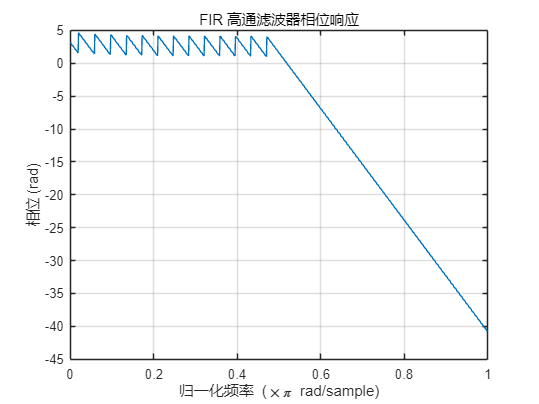


% 绘制相位响应 (绿色注释：展开相位)
figure;
plot(w/pi, unwrap(angle(H)));
grid on;
xlabel('归一化频率 (\times\pi rad/sample)');
ylabel('相位 (rad)');
title('FIR 高通滤波器相位响应');